## Callback Subscriber for LaserScan Messages

**12)** Restart the Turtlebot Gazebo simulation in ROS from the command line. Launch the Turtlebot navigation and Rviz with the `turtlebot3_navigation` launch file from a second terminal. Shutdown the current connection to the ROS master in Matlab `rosshutdown` in case the current master is still running. Reconnect with `rosinit` to the new master.

rosshutdown
rosinit('http://ubuntu:11311/')

Initializing global node /matlab_global_node_86347 with NodeURI http://192.168.2.111:55196/


**13)** Define a handle class s`canHa`ndle in a new file named `scanHandle.m`. A convenient way to do so is by utilizing Matlabs class template (*New* -> *Class*). The class `scanHandle` has no `methods` and the `properties` resemble the main properties of the message `sensor_msgs/LaserScan.msg` which is published on the `/scan` topic:

- `ranges` : array of range readings in *m*

- `angles` : array of angles in *rad*

- `rmin` : minimum range reading

- `phimin` : angle of minimum range reading

    The properties `rmin` and `phimin` become later relevant in the context behavior based obstacle avoidance.

**14)** Implement a Callback function for the `/scan` topic at the bottom of this script.

**15)** Instantiate a `scanHandle` and a Callback subscriber `scanSubCallback` that subscribes to the `/scan` topic and refers to your Callback function `scanCallback`.

**16)** Augment the callback subscriber function `scanCallback` (at the bottom of this script) such that it determines the distance `rmin` and heading `phimin` towards the most relevant obstacle.

**17)** Implement a loop in which the heading and the distance to the nearest object are plotted as an arrow starting at the origin. The arrow should point from the origin to the nearest obstacle. Utilize the previously created `scanHandle` which is filled in the `scanSubCallback` function.

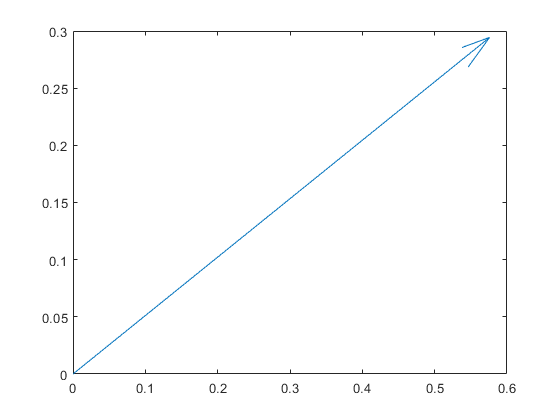

maxTime = 20; 

%define rate object for program loop in Hz and reset
rateObj = robotics.Rate(5);
rateObj.reset;

laserScan = scanHandle;
beta = 0.5;
robotradius = 0.2;
scanSub = rossubscriber('/scan',{@scanCallback, laserScan, beta, robotradius});

% program loop
while rateObj.TotalElapsedTime < maxTime
    quiver(0,0,laserScan.rmin*cos(laserScan.phimin),laserScan.rmin*sin(laserScan.phimin))
    % wait for loop to be executed ad rateObj.Rate
    waitfor(rateObj);
end

## Finish

clear subscribers at the end of the code

clear scanSub
disp('finished');

finished


**14)** Implement a Callback function for the `/scan` topic,

which converts the `LaserScanMsg` into to the `scanHandle` object `laserScan`.The callback function extracts the range readings and corresponding angles (function `readScanAngles`) from the `sensor_msgs/LaserScan.msg `message and assigns them to the properties `ranges`, `angles`.

**16)** Augment the callback subscriber function `scanCallback` such that it determines the distance `rmin` and heading `phimin` towards the most relevant obstacle. The relevance of an obstacle depends on its proximity to the robot but also to the relative heading. Nearby obstacles in longitudinal direction are far more relevant for obstacle avoidance than remote obstacles or obstacles in lateral direction. Thus the scaled obstacle distance $$\hat r_i$$ of the scan $$r_i,\phi_i$$ in polar coordinates is given by


$$\hat r_i = (r_i- r_{robot}) (1.0 - \beta cos(\phi_i))$$


in which $$\beta \in  [0,1]$
$ determines the shrinkage of the absolute distance $$r_i$
$ along the longitudinal distance as illustrated in the figure below. 

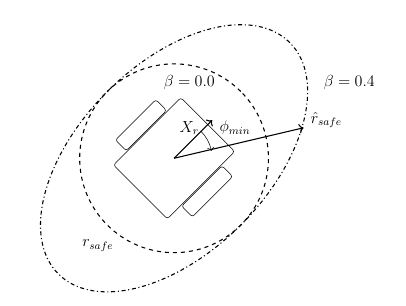

The robot radius $$r_{robot}$
$ is subtracted from the range readings $$r_i$$ as those measure the distance to the center of the robot rather than the distance to the robots perimeter. `beta` and `robotradius` are additional input parameters to the callback function.

Determine the scan with minimal scaled obstacle distance $$\hat r_i$
$ 

	
$$j = \text{argmin}_i \hat r_i$$


and assign $$r_{min}=r_j - r_{robot}$$ and $$\phi_{min}=\phi_j$
$ to the `scanHandle `properties `rmin` `and` `phimin`

The original laser range readings $$r_i$
$ are w.r.t. the center of the robot. For a safe obstacle avoidance it is important to consider the robots diameter by subtracting $$r_{robot}$
$ from $$r_j$$. That way obstacle avoidance behavior inputs `rmin`, `phimin` reflect the true spatial separation between the robots circular perimeter and the obstacle.

function scanCallback(~, scanMsg, laserScan, beta, robotradius)
    % laser scanner callback function
    % ========================================================================
    %
    %  
    %  scanCallback (~,scanMsg,laserscanReceive)
    %
    %  Input:
    %    scanMsg: laserscan ROS message Object
    %    laserscan: scanHandle

    
    % Write Data from ScanMsg to global class handle laserscan
    laserScan.ranges = scanMsg.Ranges;
    laserScan.angles = readScanAngles(scanMsg);
    % minimal distance (rmin) to any surrounding object
    [~, idx] = min((laserScan.ranges-robotradius).*...
        (1.0-beta*cos(laserScan.angles)));
    laserScan.rmin = laserScan.ranges(idx)-robotradius;
    % angle of the minimal distance (phimin) from robots point of view
    laserScan.phimin = laserScan.angles(idx);
end

